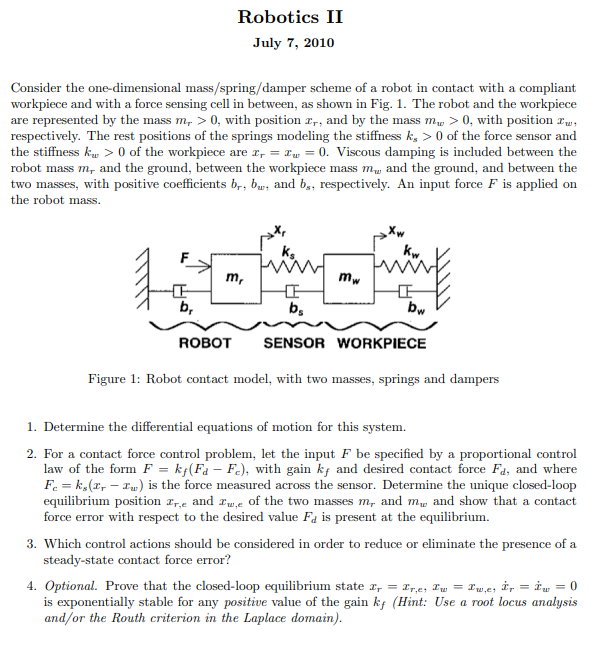

% % % This part is isolated from previous section
clear;clc
% %
% % % syms k q1(t) q2(t) q3(t)
sigma = [1,1];
R2Robot=['ss';'xx';sigma];
n = length(sigma);
t = sym('t', 'real');

x_r=sym('x_r','real');
x_r_dot=sym('x_dot_r','real');
x_r_ddot=sym('x_ddot_r','real');

x_w=sym('x_w','real');
x_w_dot=sym('x_dot_w','real');
x_w_ddot=sym('x_ddot_w','real');

m_r=sym('m_r','real');
m_w=sym('m_w','real');

F_r=sym('F_r','real');
F_w=0*sym('F_w','real');


b_r=sym('b_r','real');
b_s=sym('b_s','real');
b_w=sym('b_w','real');

k_r=0*sym('k_r','real');
k_s=sym('k_s','real');
k_w=sym('k_w','real');

q = sym('q_', [n 1],'real');
q_derivated=derivate_D(q,n,t,'q');
qd = q_derivated.dot;
qdd = q_derivated.ddot;

z = Gen_param(n);

z.sigmaD=R2Robot;
% z.q=q;
% z.q_dot=qd;
% z.q_ddot=qdd;

z.q=[x_r,x_w]';
z.q_dot=[x_r_dot,x_w_dot]';
z.q_ddot=[x_r_ddot,x_w_ddot]';
z.k=[k_r,k_s,k_w]' ;
z.b=[b_r,b_s,b_w]' ;
z.m_spring=[m_r,m_w]' ;
z.F=[F_r,F_w]' ;


[spring_models,F_springs_,z]=Spring_model(z);

% F_spring_(1,1)=spring_models(1).F_;
% F_spring_(2,1)=spring_models(2).F_;
% F_spring_=collect(expand(F_spring_),[z.k;z.b])

F_spring_=collect(expand(F_springs_),[z.k;z.b])

$$F\_spring\_ = \left(\begin{array}{c} \left(x_{r}-x_{w}\right)\,k_{s}+{\dot{x}}_{r}\,b_{r}+\left({\dot{x}}_{r}-{\dot{x}}_{w}\right)\,b_{s}+m_{r}\,{\ddot{x}}_{r}\\ \left(x_{w}-x_{r}\right)\,k_{s}+x_{w}\,k_{w}+\left({\dot{x}}_{w}-{\dot{x}}_{r}\right)\,b_{s}+{\dot{x}}_{w}\,b_{w}+m_{w}\,{\ddot{x}}_{w} \end{array}\right)$$

expand(sum(F_spring_))

$$ans = b_{r}\,{\dot{x}}_{r}+b_{w}\,{\dot{x}}_{w}+k_{w}\,x_{w}+m_{r}\,{\ddot{x}}_{r}+m_{w}\,{\ddot{x}}_{w}$$

## axis offset

% % 
% h=sym('h','real')
% %x,y,z
% z.xyx_offset=sym(zeros(3,n));
% z.xyx_offset(:,1)=[0,h,0]';%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=true;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end

% 
% %
% %
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}


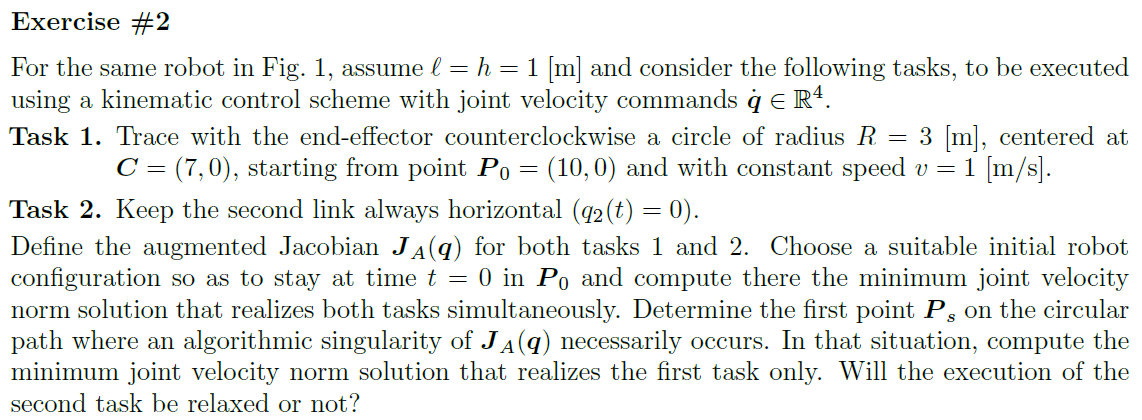

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,0,0,0];
% R2Robot=['prrr';'xxxx';sigma]
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym("l","real");
% % l_0=1%sym('l','real')
% h=sym('h','real');
% h_=h%1;
% z.opt_expr={[l;h],[l_0,l_0,l_0,l_0,h_]'};%not necessary
% 
% % z.rcdefined=true;

## axis offset

% % 
% % 
% % %x,y,z
% z.xyx_offset=sym(zeros(3,n));
% z.xyx_offset(:,1)=[0,h,0]';%

% % %Global q reference?
% % % clear
% % % z.q_global
% z.global_q_reference=true;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end

Defining task order

% pd={sym('pd_1_',[2,1],'real'),sym('pd_2_',[1,1],'real')};
% % z.task_defined={struct('f','end_effector','pd_',pd{2},'pd_dot_',[0.1,-0.5]'),struct('f',sum([q(1),q(2),0]),'pd_',pd{1},'pd_dot_',[0])} %pc is note necessary
% z.task_defined={struct('f','end_effector','pd_',pd{1}),struct('f',q(2),'pd_',pd{2})} ;%pc is note necessary
% %
% z.task_defined

% % % xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z);
% % % VarShortRobot.M
% % % angle_desired=[0,0]
% % % l(1)=0
% % % [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% f
% J
% % % M
% % % Pc
% % % simplify((Ti'))
% % % vc
% % % simplify(Trans.PTotal)
% % % Trans.PPartial{:}
% % J

## rank of J

% rank(J)
% J(:,2:end)
% det(J(:,2:end))

% rd_1=f(1:2,:)
% rd_2=f(3:end,:)

## redundancy task with prioriy

% replace_values=false
% % vars2replace=[z.q;z_q_dot_k,z.]
% z.q_=[0,pi/2,-pi/2]';
% 
% [q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);

% q_dot_k{:};
% z_task.J_k{:};
% z_task.J_k_pinv{:};
% z_task.P_A_k{:};
% 
% % z_task.q_dot_k_{:}
% % z_task.J_k_{:}
% % z_task.J_k_pinv_{:}
% % z_task.P_A_k_{:}

## defining function trajectory

% z_path_params.func_name="circular";
% z_path_params.replacevars=true;
% z_path_params.dir=1;
% z_path_params.C_=[7,0]';
% z_path_params.R_=3;
% z_path_params.v_=1;
% xyonly_=true
% z_path = common_trajectory_func(z_path_params,xyonly_);

% z_path.rd_theta
% z_path.rd_t
% z_path.rd_t_dot
% z_path.rd_t_ddot
% if(z_path_params.replacevars)
%     z_path.rd_theta_
%     z_path.rd_theta_dot_
%     z_path.rd_theta_ddot_
%     
%     z_path.rd_t_
%     z_path.rd_t_dot_
%     z_path.rd_t_ddot_
%     
% end

% P_0=subs(z_path.rd_theta_,z_path.theta,0)%[10,0]';
% rd_dot_0_=subs(z_path.rd_theta_dot_,z_path.theta,0)%sym([0,1,0])'; %v=1
% z_task.f_k{1}
% f_k_red=simplify(subs(z_task.f_k{1},q(2),0))
% q_sol1=solve(f_k_red==P_0,q)
% 
% [qdvarray_,qdvnames_,vartosolve2] = solvetoarray(q_sol1,q)% no iptimal solution
% f_k_red_=subs(f_k_red,q,qdvarray_)
% 
% q_sol2_=[8,0,0,-pi/2]'
% f_k_red_=subs(f_k_red,q,q_sol2_) %% optimal solution
% q_red=[q(1),q(3),q(4)]'
% % q_dot_red=[q_dot(1),q_dot(3)]'
% J_k_red=jacobian(f_k_red,q_red)

% % % eq3=det(J_k_red(:,2:end))~=0
% % % 
% % % q_sol1=vpasolve([f_k_red==P_0;eq3])%,q_red)
% % % [qdvarray_,qdvnames_,vartosolve2] = solvetoarray(q_sol1,q)% no iptimal solution

% % 
% % q_dot_=z.q_dot;
% % q_dot_(2)=0

% % det(J_k_red(:,2:end))
% % display("singular in the configuration q=[6,0,pi/2,pi/2]'")

J_A_0 evaluation

% J_A_0_=subs(J,q,q_sol2_)
% q_dot_0_=pinv(J_A_0_)*[rd_dot_0_;0]%%succesfully done

J_A_s evaluation

% P_0=subs(z_path.rd_theta_,z_path.theta,pi/2)%[10,0]';
% rd_dot_s_=subs(z_path.rd_theta_dot_,z_path.theta,pi/2)%sym([0,1,0])'; %v=1
% q_s_=[6,0,pi/2,pi/2]'
% J_A_s_=subs(J,q,q_s_)
% q_dot_s_=pinv(J_A_s_)*[rd_dot_s_;0]%%succesfully done

## tessting solution

% rd_dot_s2_=J_A_s_*q_dot_s_%% succesfully completed!!!

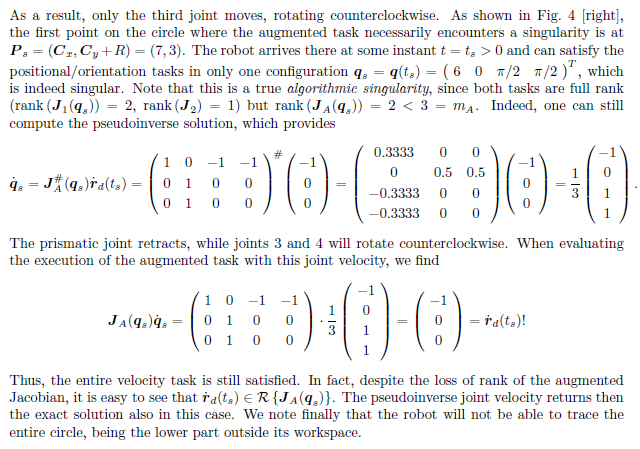

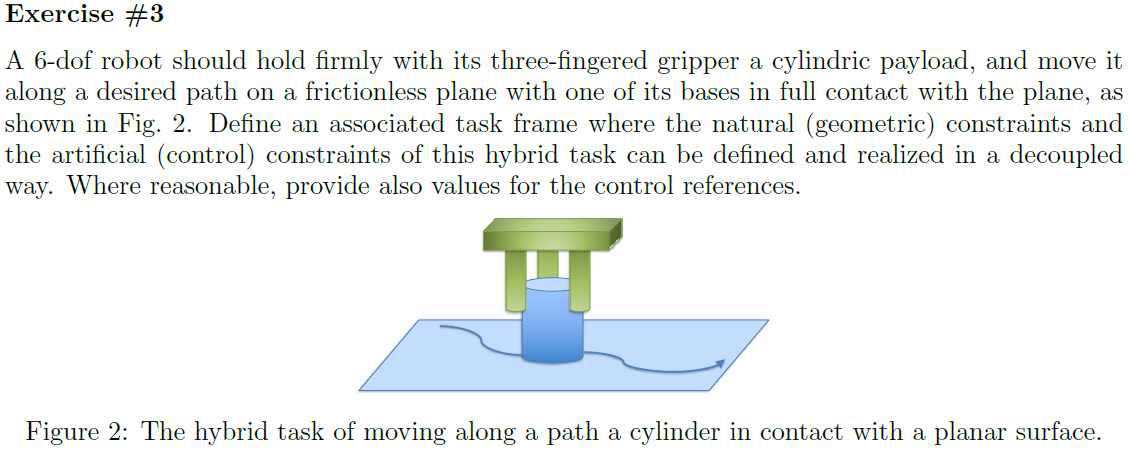

## natural cosntrains

## see one noe

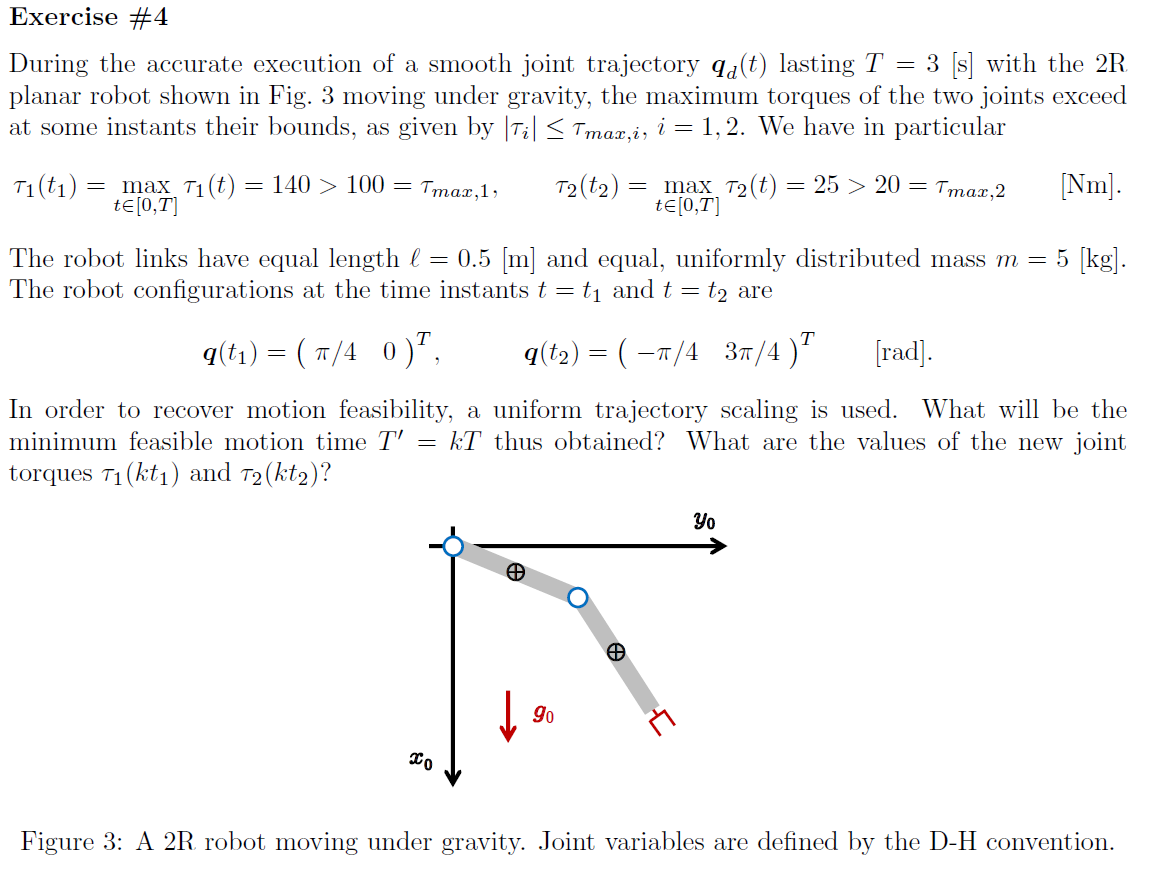

% % This part is isolated from previous section
% clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% R2Robot=['rr';'xx';sigma]
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real')
% m_0=sym('m','real')
% z.opt_expr={[l;dc],[l_0,l_0,l_0/2,l_0/2]'};%not necessary
% l_=[l_0,l_0]';
% m_=[m_0,m_0]';
% % z.rcdefined=true;

## axis offset

% 
% % h=sym('h','real')
% % %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,0*h,0]'%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=false;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end

% 
% %
% %
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l_, m_, dc, g, isMotor);

% g_q
% U{:}
% 

## evaluating gravity torques

## t1

% q1_=[pi/4,0]'
% l_def=sym('l','real')
% m_def=sym('m','real')
% l_=0.5
% m_=5
% g0_=9.81
% 
% vars2replace=[l_def;m_def;g0;q]
% vars2replace_=[l_;m_;g0_;q1_]
% g_q_t1_=vpa(subs(g_q,vars2replace,vars2replace_))

## t2

% q2_=[-pi/4,3*pi/4]'
% vars2replace=[l_def;m_def;g0;q]
% vars2replace_=[l_;m_;g0_;q2_]
% g_q_t2_=vpa(subs(g_q,vars2replace,vars2replace_))

## evaluating

% g1_torque_=g_q_t1_(1)
% g2_torque_=g_q_t2_(2)
% tau_max_1=100;
% tau_max_2=20;
% tau_q1_t1=140;
% tau_q2_t2=25;
% k1=sqrt((tau_q1_t1-g1_torque_)/(tau_max_1-g1_torque_))
% k2=sqrt((tau_q2_t2-g2_torque_)/(tau_max_2-g2_torque_))%% this is the maximun k we have to use this

## recomputing new maximun torques

% tau_q1_tk=(tau_q1_t1-g1_torque_)/k2^2+g1_torque_
% tau_q2_tk=(tau_q2_t2-g2_torque_)/k2^2+g2_torque_

## Exercise 5

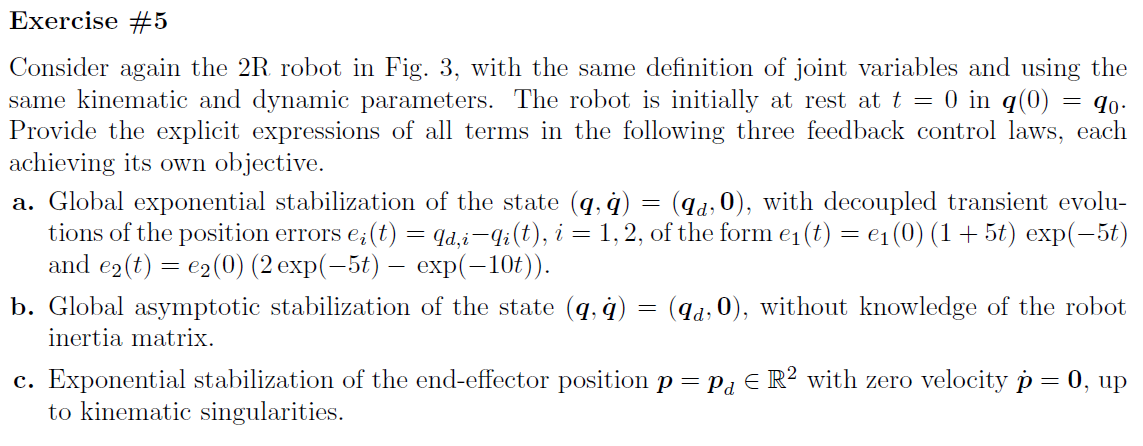

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';

defining z struct

% R2Robot=['rr';'xx';sigma]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real')
% m_0=sym('m','real')
% z.opt_expr={[l;dc],[l_0,l_0,l_0/2,l_0/2]'};%not necessary
% l_=[l_0,l_0]';
% m_=[m_0,m_0]';
% % z.rcdefined=true;

## axis offset

% 
% % h=sym('h','real')
% % %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,0*h,0]'%

% % %Global q reference?
% % % clear
% % % z.q_global
% % z.global_q_reference=false
% % if(z.global_q_reference)
% %     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD)
% % end

% 
% %
% %
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l_, m_, dc, g, isMotor)

% g_q
% U{:}

## control

## a)

% 
% t=sym('t','real');
% s=sym('s','real');
% e_1_0=sym('e_1_0','real');
% e_2_0=sym('e_2_0','real');
% e_=[e_1_0*(1+5*t)*exp(-5*t);e_2_0*2*exp(-5*t)-exp(-10*t)]
% z_global_exponential = feedback_linearization_control_global_exponential(z,e_)

% e_=z_global_exponential.e_
% e_dot_=z_global_exponential.e_dot_
% e_ddot_=z_global_exponential.e_ddot_

% K_D=diag(sym('K_D_',[2,1],'real'))
% K_P=diag(sym('K_P_',[2,1],'real'))

% simplify(e_ddot_+K_D*e_dot_+K_P*e_)

## identifitying poles

% a_law_=z_global_exponential.law_
% a_law_laplace=z_global_exponential.law_laplace_
% 
% poles(a_law_laplace(1),s)
% poles(a_law_laplace(2),s)

## another way... did't work haha

% % % K_D=z_global_exponential.mK_D;
% % % K_P=z_global_exponential.mK_P;
% % % a_law_factors_1=factor(a_law_(1))
% % % kp_1_sol=solve(a_law_factors_1(2)==0,[K_P(1);K_D(1)])
% % % simplify(subs(a_law_factors_1(2),kp_1_sol))

## b)By hand